syms t
assume(t, ["real", "positive"])

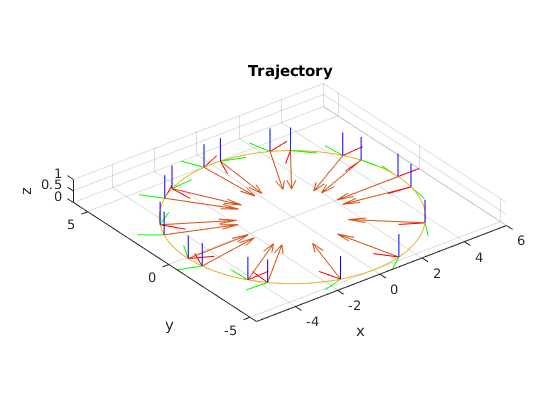

TF frames displayed: 19


% Axis of rotation as a function of time
alpha = [
    0;
    0;
    1;
];
alpha = alpha / norm(alpha);
% Angle of rotation as a function of time
%theta = 0.2*t;
theta = 0.2*t^1.5;

% Construct the quaternion using axis-angle
q_t = [
    cos(theta/2);
    sin(theta/2)*alpha;
];

r_t = [
    5*cos(t);
    5*sin(t);
    0;
];

n = 342;
t_0 = 0;
t_end = 10;
tspan = linspace(t_0, t_end, n);

tab_sim = generate_trajectory(tspan, r_t, q_t);
viz_trajectory(tab_sim.r, tab_sim.q, "a", tab_sim.a)

function mat = quat_vec_to_mat(q)
    % Reurnts the corresponding rotation matrix for a quaterion q, in
    % homogenous coordinates
    [w, x, y, z] = deal(q(1), q(2), q(3), q(4));

    % Formula from http://groups.csail.mit.edu/graphics/classes/6.837/F01/Lecture09/Slide24.html
    mat = [
       1-2*y^2-2*z^2, 2*x*y-2*w*z,   2*x*z+2*w*y,   0;
       2*x*y+2*w*z,   1-2*x^2-2*z^2, 2*y*z-2*w*x,   0;
       2*x*z-2*w*y,   2*y*z+2*w*x,   1-2*x^2-2*y^2, 0;
       0,             0,             0,             1;
    ];
end

% Construct SE(3) pose matrix out of a quaternion and a position vector
function pose_out = construct_pose(q, r)
    pose_out = sym(quat_vec_to_mat(q));
    pose_out(1:3, 4) = r;
end

% Invert quaternion
% The inverse of a quaternion's rotation is just the complex-conjugate
% of the quaternion
function q_out = invert_quat(q)
    q_out = q;
    q_out(2:4) = -q(2:4);
end